set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter', "latex");
set(groot, 'defaulttextinterpreter',"latex");
colors=['b' 'k' 'r' 'g' 'y' 'c' 'm' 'b' 'k' 'r' 'g' 'y' 'c' 'm' 'b' 'k' 'r' 'g' 'y' 'c' 'm'  'b' 'k' 'r' 'g' 'y' 'c' 'm'];

# SID Methods Compared to Original Time Series Data

Script performs the following

- Load DEAP data for a single subject

- Selects a single trial for that subject

- Visualize the original (detrended) data

- Run 4 output only system ID algorithms to determine A,C matricies 

- Compare results to original time series

## Prepare Dataset

s02=load('s08.mat');
subject=09;
basename='S015E';
extension='.png';
trial=20;

Y=s02.data(:,[3,4,31,27,28],:); %selecting the F row, across the top of the head
Y=reshape(Y,[1,5,8064*40]);
%Y=s02.data(trial,[3,4,31,27,28],[1:500]); %subsample the time dimension


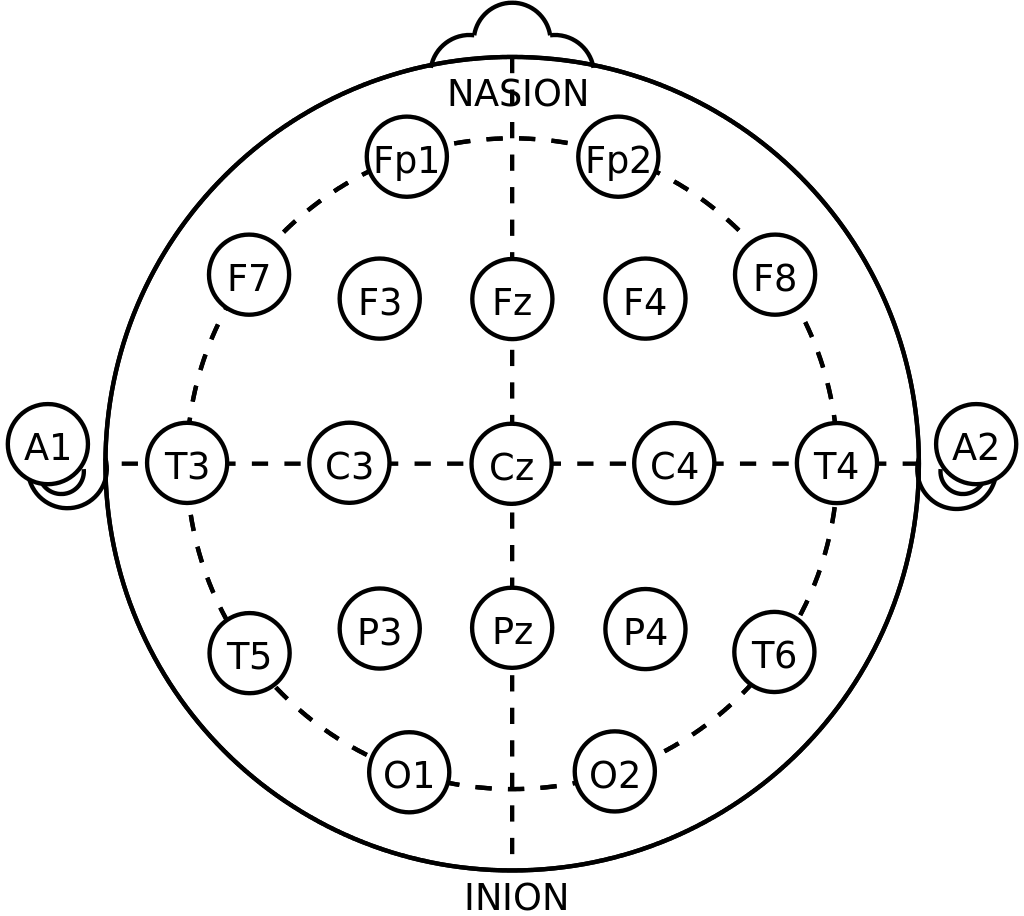

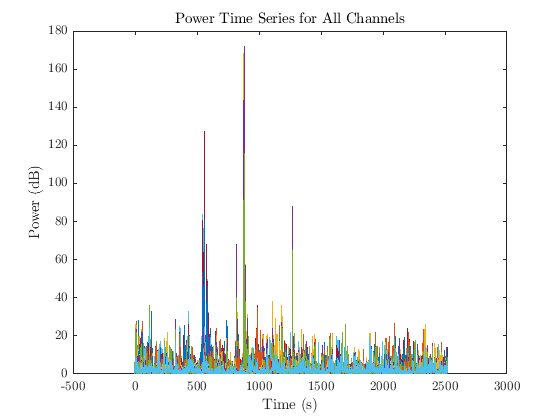

Y=squeeze(Y);
Y=Y';
channels=[3,4,31,27,28];
Pxx=cell(1,length(channels));
F=cell(1,length(channels));
tvec=cell(1,length(channels));
for iii=1:length(channels)
    [Pxx{iii},F{iii},tvec{iii}]=compute_eeg_power(Y(:,iii),128,63*40);
end
ind_delta=find(F{1}<=4);
ind_theta=find(F{1}>=4 & F{1}<=8);
ind_alpha=find(F{1}>=8 & F{1}<=12);
ind_beta=find(F{1}>=12 & F{1}<=30);
ind_all=find(F{1}<=30);
mean_delta=cell(1,length(channels));
mean_alpha=cell(1,length(channels));
mean_beta=cell(1,length(channels));
mean_theta=cell(1,length(channels));
Y_final=[];
for iii=1:length(channels)
    mean_alpha{iii}=mean(Pxx{iii}(ind_alpha,:));
    mean_beta{iii}=mean(Pxx{iii}(ind_beta,:));
    mean_theta{iii}=mean(Pxx{iii}(ind_theta,:));
    mean_delta{iii}=mean(Pxx{iii}(ind_delta,:));
    Y_final=[Y_final, mean_delta{iii}', mean_theta{iii}',mean_alpha{iii}', mean_beta{iii}'];
end
figure
plot(tvec{1},Y_final)
xlabel('Time (s)')
ylabel('Power (dB)')
title('Power Time Series for All Channels')

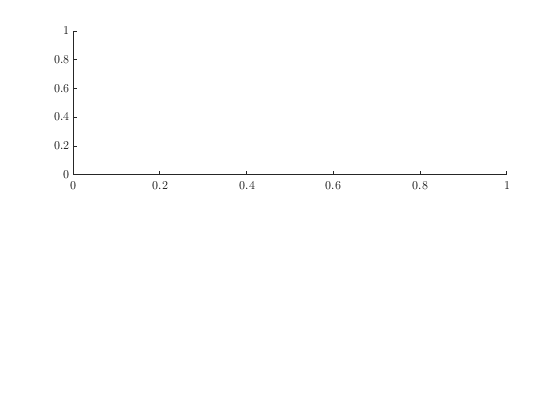

Error using plot
Vectors must be the same length.

Y_final=Y_final';

t = linspace(0,63,length(Y_final));
fs=128;
fs=367/63;
T=1/fs;


## Run Output Only Algorithms

Includes traditional OMA, the later developed OMA-data, the Matlab default n4sid, and NeXT-ERA. 

### 1. OMA

[1] "System Identification Methods for (Operational) Modal Analysis: Review and Comparison" by Edwin Reynders in Archives of Computational Methods in Engineering, Vol. 19, No. 1, doi:10.1007/s11831-012-9069-x

Assumes outputs are corrupted by additive sensor noise, and **inputs are stochastic, unobserved.**

order = 30;
s = 2*order;

[A_cov,C_cov,G_cov,R0_cov] = ssicov(Y_final,order,s);

SSI-cov status:
  forming block Hankel matrix...
  performing singular value decomposition...
  generating system matrices A,C,G for 30 model orders...
SSI-cov finished.


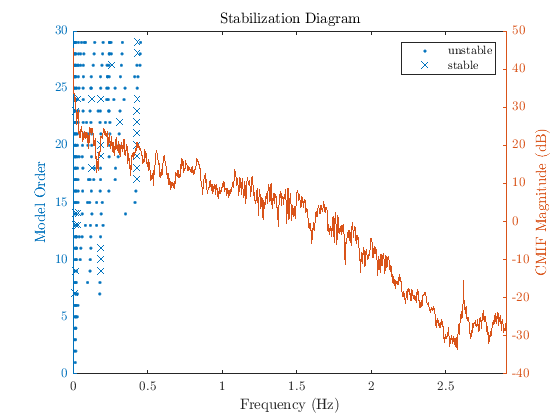


err = [5e-3,0.1,0.98];
[IDs_cov] = plotstab(A_cov,C_cov,Y_final,T,[],err);

Classify a pole as stable in freq if its natural freq changes by less than 0.5% as the model order increases. Classify pole as stable if damping ratio changes by less than 10% as model order increases. Arbitrary, and based on guess and check.

[fn_cov,zeta_cov,Phi_cov] = modalparams(A_cov,C_cov,T);
opt_order=27; %purely just cause here, seems to have the most modes
eig(A_cov{opt_order})

ans =    0.8817 + 0.4645i
   0.8817 - 0.4645i
   0.8809 + 0.4393i
   0.8809 - 0.4393i
   0.9245 + 0.3372i
   0.9245 - 0.3372i
   0.9295 + 0.2630i
   0.9295 - 0.2630i
   0.9378 + 0.2482i
   0.9378 - 0.2482i


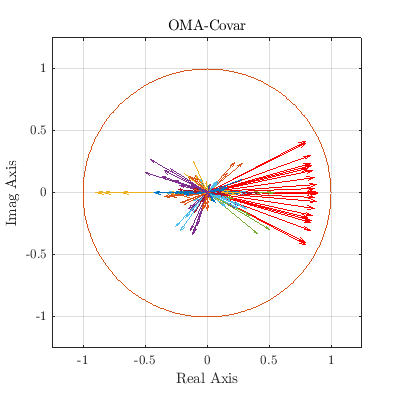

real_part_OMA=real(eig(A_cov{opt_order}));
imag_part_OMA=imag(eig(A_cov{opt_order}));
figure
set(gcf,'units','points','position',[25,25,300,300])
circle(0,0,1)
hold on

for i=1:opt_order
    quiver (0,0,real_part_OMA(i),imag_part_OMA(i), 'r')
    hold all
end
xlim([-1.25 1.25])
ylim([-1.25 1.25])
title('OMA-Covar Eigenvalues')
xlabel('Real Axis')
ylabel('Imag Axis')
grid on
sys_cov=ss(A_cov{opt_order},[],C_cov{opt_order},0);
% figure
% initial(sys_cov,[0 0 0 0 0 0 0 0.1 0 0 0 0 0 0 0 0 0 0]) %AUTOMATE this
norm_cov=abs(max(Phi_cov{opt_order}, [], 'all')); %determine max value
Phi_cov{opt_order}=Phi_cov{opt_order}/norm_cov; %normalize the one of interest

circle(0,0,1)
hold on

for i=1:size(Phi_cov{opt_order},2)
    quiver(zeros(length(Phi_cov{opt_order}(:,i)),1),zeros(length(Phi_cov{opt_order}(:,i)),1),real(Phi_cov{opt_order,1}(:,i)),imag(Phi_cov{opt_order,1}(:,i)))
    hold all
    pbaspect([1 1 1])    
end
title('OMA-Covar')
xlim([-1.25 1.25])
ylim([-1.25 1.25])
grid on

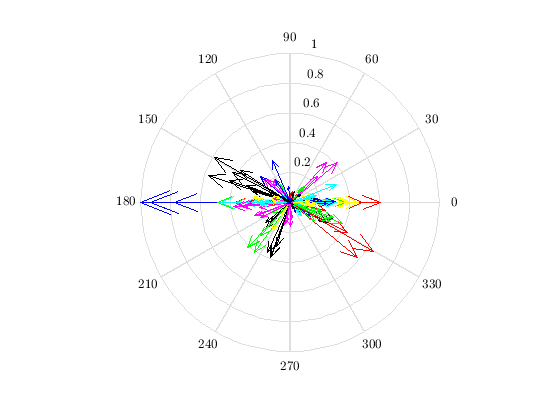

figure
for i=1:size(Phi_cov{opt_order},2)
    hidden_arrow = compass(1,0);
    hidden_arrow.Color = 'none';
    hold on
    compass(Phi_cov{opt_order}(:,i),colors(i))
    hold on
end

### 2. OMA Data

Same basic principles as OMA, but with less assumptions on the nature of the input. 

Assumes no input, free vibration under initial conditions

[2] "Subspace Identification for Linear Systems" by Peter van Overschee and Bart de Moor, doi:10.1007/978-1-4613-0465-4

[A_data,C_data,G_data,R0_data] = ssidata(Y_final,order,s);

SSI-data status:
  forming shifted data matrix...
  projecting raw data...
  performing singular value decomposition...
  generating system matrices A,C,G for 30 model orders...
SSI-data finished.


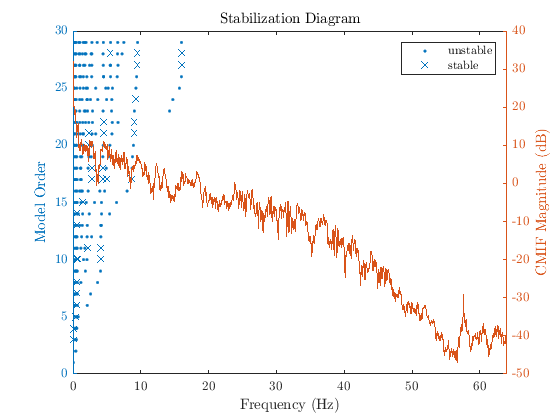

[fn_data,zeta_data,Phi_data] = modalparams(A_data,C_data,T);
[IDs_data] = plotstab(A_data,C_data,Y_final,T,[],err);

eig(A_data{opt_order})

ans =    0.6886 + 0.6887i
   0.6886 - 0.6887i
   0.8779 + 0.4416i
   0.8779 - 0.4416i
   0.9254 + 0.3118i
   0.9254 - 0.3118i
   0.9364 + 0.2569i
   0.9364 - 0.2569i
   0.8754 + 0.2262i
   0.8754 - 0.2262i


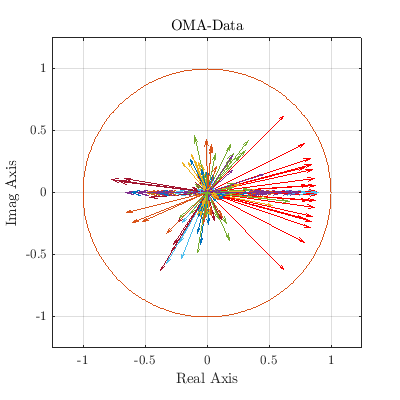

real_part_data=real(eig(A_data{opt_order}));
imag_part_data=imag(eig(A_data{opt_order}));
figure
set(gcf,'units','points','position',[25,25,300,300])
circle(0,0,1)
hold on

for i=1:opt_order
    quiver (0,0,real_part_data(i),imag_part_data(i), 'r')
    hold all
end
xlim([-1.25 1.25])
ylim([-1.25 1.25])
title('OMA-Data Eigenvalues')
xlabel('Real Axis')
ylabel('Imag Axis')
grid on
sys_data=ss(A_data{opt_order},[],C_data{opt_order},0);
% figure
% initial(sys_data,[0 0 0 0 0 0 0 0.1 0 0 0 0 0 0 0 0 0 0])
Phi_data=Phi_data';
norm_data=abs(max(Phi_data{opt_order}, [], 'all')); %determine max value
Phi_data{opt_order}=Phi_data{opt_order}/norm_data; %normalize the one of interest

circle(0,0,1)
hold on

for i=1:size(Phi_data{opt_order},2)
    quiver(zeros(length(Phi_data{opt_order}(:,i)),1),zeros(length(Phi_data{opt_order}(:,i)),1),real(Phi_data{opt_order,1}(:,i)),imag(Phi_data{opt_order,1}(:,i)))
    hold all
    pbaspect([1 1 1])
end
xlim([-1.25 1.25])
ylim([-1.25 1.25])
grid on
title('OMA-Data')

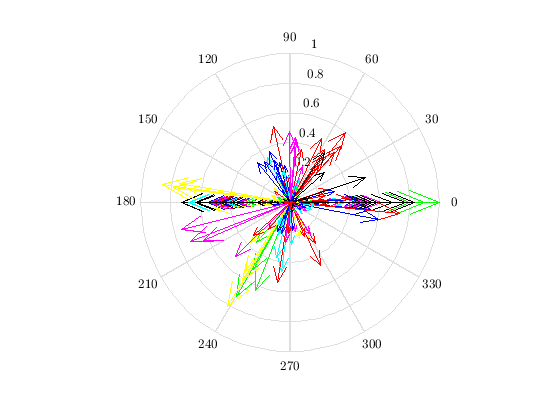

figure
for i=1:size(Phi_data{opt_order},2)
    hidden_arrow = compass(1,0);
    hidden_arrow.Color = 'none';
    hold on
    compass(Phi_data{opt_order}(:,i),colors(i))
    hold on
end

### 3. n4sid

This is the Matlab default system id algorithm. It generally shows better results with B data, which we don't have.

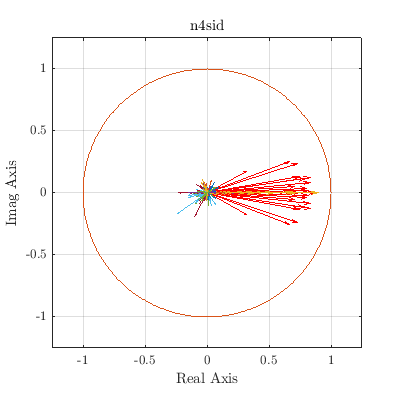

data = iddata(Y_final',[],T);
sys = n4sid(data,opt_order);
[A_n4,~,C_n4,~] = ssdata(sys);
real_part_n4=real(eig(A_n4));
imag_part_n4=imag(eig(A_n4));
figure
set(gcf,'units','points','position',[25,25,300,300])
circle(0,0,1)
hold on

for i=1:length(real_part_n4)
    quiver (0,0,real_part_n4(i),imag_part_n4(i), 'r')
    hold all
end
xlim([-1.25 1.25])
ylim([-1.25 1.25])
title('n4sid Eigenvalues')
xlabel('Real Axis')
ylabel('Imag Axis')
grid on
sys_n4=ss(A_n4,[],C_n4,0);
% figure
% initial(sys_n4,[0 0 0 0 0 0 0 0.1 0 0 0 0 0 0 0 0 0 0])
[fn_n4,zeta_n4,Phi_n4] = modalparams(A_n4,C_n4,T);
Phi_n4=Phi_n4{1};
norm_n4=abs(max(Phi_n4, [], 'all'));
Phi_n4=Phi_n4/norm_n4;
circle(0,0,1)
hold on

for i=1:length(Phi_n4(1,:))
    quiver(zeros(length(Phi_n4(:,1)),1),zeros(length(Phi_n4(:,1)),1),real(Phi_n4(:,i)),imag(Phi_n4(:,i)))
    hold all
    pbaspect([1 1 1])
end
xlim([-1.25 1.25])
ylim([-1.25 1.25])
grid on
title('n4sid')

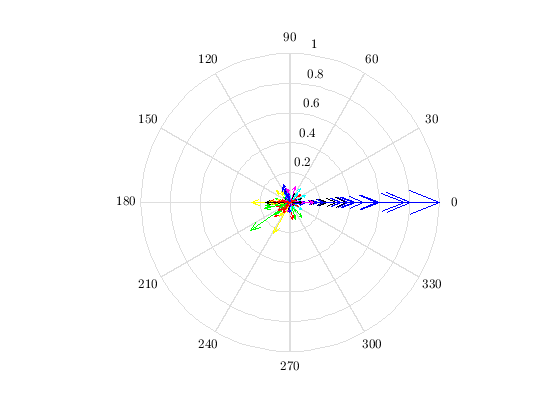

figure
for i=1:size(Phi_n4,2)
    hidden_arrow = compass(1,0);
    hidden_arrow.Color = 'none';
    hold on
    compass(Phi_n4(:,i),colors(i))
    hold on
end

### 4. NeXT-ERA

[3] R. Pappa, K. Elliott, and A. Schenk, A consistent-mode indicator for the eigensystem realization algorithm, Journal of Guidance Control and Dynamics (1993), 1993.

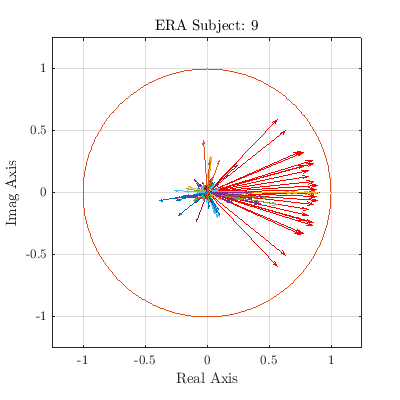

[NeXT]=NExTFERA(Y_final,5,500,14,0.3,fs,200,80,opt_order,10,1);
real_part_NeXT=real(eig(NeXT.Matrices.A));
imag_part_NeXT=imag(eig(NeXT.Matrices.A));
figure
set(gcf,'units','points','position',[25,25,300,300])
circle(0,0,1)
hold on

for i=1:length(real_part_NeXT)
    quiver (0,0,real_part_NeXT(i),imag_part_NeXT(i), 'r')
    hold all
end
xlim([-1.25 1.25])
ylim([-1.25 1.25])
title('NeXT-ERA Eigenvalues')
xlabel('Real Axis')
ylabel('Imag Axis')
grid on
sys_NeXT=ss(NeXT.Matrices.A,[],NeXT.Matrices.C,0);
% figure
% initial(sys_NeXT,[0 0 0 0 0 0 0 0.1 0 0 0 0 0 0 0 0 0 0])
[fn_NeXT,zeta_NeXT,Phi_NeXT] = modalparams(NeXT.Matrices.A,NeXT.Matrices.C,T);
Phi_NeXT=Phi_NeXT{1};
norm_NeXT=abs(max(Phi_NeXT, [], 'all'));
Phi_NeXT=Phi_NeXT/norm_NeXT;
circle(0,0,1)
hold on

for i=1:length(Phi_NeXT(1,:))
    quiver(zeros(length(Phi_NeXT(:,1)),1),zeros(length(Phi_NeXT(:,1)),1),real(Phi_NeXT(:,i)),imag(Phi_NeXT(:,i)))
    hold all
    pbaspect([1 1 1])
    axis equal
end
xlim([-1.25 1.25])
ylim([-1.25 1.25])
grid on
title(['ERA Subject: ' num2str(subject)])

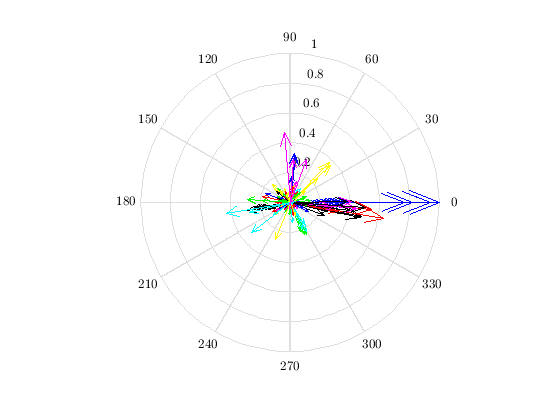

figure
for i=1:size(Phi_NeXT,2)
    hidden_arrow = compass(1,0);
    hidden_arrow.Color = 'none';
    hold on
    compass(Phi_NeXT(:,i),colors(i))
    hold on
end

## Working Questions:

- A matrices aren't stable. Lots of spikes in the original data drive this. (looks like unstable jet plane inputs to me)

- Difficult to select proper system order (generally true in the data, but hard to compare since I can't line up impulse to impulse)

- Generates a new A and C matrix for every subject and emotion. (Average the A's? Do other fields have non-deterministic ss models?)

- Wild Variance from subject to subject

Technical details: [Link](https://link.springer.com/article/10.1007/s11831-012-9069-x)